clc;
clear;
close all;

load('modelo_lin.mat')


latmod

latmod =
 
  A = 
                 v           p
   v        -0.875      0.8751
   p        -2.831      -16.14
   r         1.706      0.5154
   phi           0           1
   psi           0           0
 
                 r         phi
   v        -16.82       9.791
   p         3.377           0
   r        -2.783           0
   phi     0.05385  -1.455e-24
   psi       1.001  -2.706e-23
 
               psi
   v             0
   p             0
   r             0
   phi           0
   psi           0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p
   beta  0.05882        0
   p           0        1
   r           0        0
   phi         0        0
   psi         0        0
 
               r      phi
   beta        0        0
   p           0        0
   r           1        0
   phi         0        1
   psi         0        0
 
        

linmodel

linmodel =
 
  A = 
                 phi
   phi    -1.455e-24
   theta  -3.665e-24
   psi    -2.706e-23
   p               0
   q               0
   r               0
   u               0
   v           9.791
   w         0.01685
   Xe         0.9141
   Ye      8.457e-05
   Ze       0.001571
   omega           0
 
               theta
   phi     3.676e-24
   theta           0
   psi     1.976e-25
   p               0
   q               0
   r               0
   u          -9.791
   v       0.0009072
   w         -0.5272
   Xe     -5.589e-17
   Ye     -5.146e-12
   Ze            -17
   omega           0
 
                 psi
   phi             0
   theta           0
   psi             0
   p               0
   q               0
   r               0
   u               0
   v               0
   w               0
   Xe            -17
   Ye      -0.001573
   Ze              0
   omega           0
 
                   p
   phi             1
   theta           0
   psi             0
   p    

longmod

longmod =
 
  A = 
                   u
   u         -0.5961
   w         -0.7454
   q           1.042
   theta           0
   Ze       -0.05377
   omega       135.8
 
                   w
   u          0.8011
   w          -7.581
   q          -7.427
   theta           0
   Ze         0.9986
   omega       7.315
 
                   q
   u          -0.871
   w           15.72
   q          -15.85
   theta           1
   Ze              0
   omega           0
 
               theta
   u          -9.791
   w         -0.5272
   q               0
   theta           0
   Ze            -17
   omega           0
 
                  Ze
   u       5.053e-05
   w      -0.0009384
   q      -8.001e-16
   theta           0
   Ze              0
   omega    -0.08268
 
               omega
   u         0.01263
   w               0
   q        -0.01318
   theta           0
   Ze              0
   omega      -5.919
 
  B = 
          elevator  throttle
   u        0.4681         0
   w        -2.711    

# Tarea1:

## Modelo Longitudinal:

%Carga del modelo
Alongmod = longmod.A;
Blongmod = longmod.B;
Clongmod = longmod.C;
Dlongmod = longmod.D;
longmod

longmod =
 
  A = 
                   u
   u         -0.5961
   w         -0.7454
   q           1.042
   theta           0
   Ze       -0.05377
   omega       135.8
 
                   w
   u          0.8011
   w          -7.581
   q          -7.427
   theta           0
   Ze         0.9986
   omega       7.315
 
                   q
   u          -0.871
   w           15.72
   q          -15.85
   theta           1
   Ze              0
   omega           0
 
               theta
   u          -9.791
   w         -0.5272
   q               0
   theta           0
   Ze            -17
   omega           0
 
                  Ze
   u       5.053e-05
   w      -0.0009384
   q      -8.001e-16
   theta           0
   Ze              0
   omega    -0.08268
 
               omega
   u         0.01263
   w               0
   q        -0.01318
   theta           0
   Ze              0
   omega      -5.919
 
  B = 
          elevator  throttle
   u        0.4681         0
   w        -2.711    



%eliminacion de datos irrelevantes
Alongmod(abs(Alongmod)<1e-10)=0;
Blongmod(abs(Blongmod)<1e-10)=0;
Clongmod(abs(Clongmod)<1e-10)=0;
Dlongmod(abs(Dlongmod)<1e-10)=0;

longmodNames = longmod.StateName;
Blongmod=Blongmod(:,1);
Clongmod=Clongmod(4,:);
Dlongmod=Dlongmod(4,1);

G=ss(Alongmod,Blongmod,Clongmod,Dlongmod);
G.StateName=longmod.StateName

G =
 
  A = 
                   u
   u         -0.5961
   w         -0.7454
   q           1.042
   theta           0
   Ze       -0.05377
   omega       135.8
 
                   w
   u          0.8011
   w          -7.581
   q          -7.427
   theta           0
   Ze         0.9986
   omega       7.315
 
                   q
   u          -0.871
   w           15.72
   q          -15.85
   theta           1
   Ze              0
   omega           0
 
               theta
   u          -9.791
   w         -0.5272
   q               0
   theta           0
   Ze            -17
   omega           0
 
                  Ze
   u       5.053e-05
   w      -0.0009384
   q               0
   theta           0
   Ze              0
   omega    -0.08268
 
               omega
   u         0.01263
   w               0
   q        -0.01318
   theta           0
   Ze              0
   omega      -5.919
 
  B = 
              u1
   u      0.4681
   w      -2.711
   q      -134.1
   theta       0
 

G.InputName = 'elevador';
G.OutputName = 'theta';
G

G =
 
  A = 
                   u
   u         -0.5961
   w         -0.7454
   q           1.042
   theta           0
   Ze       -0.05377
   omega       135.8
 
                   w
   u          0.8011
   w          -7.581
   q          -7.427
   theta           0
   Ze         0.9986
   omega       7.315
 
                   q
   u          -0.871
   w           15.72
   q          -15.85
   theta           1
   Ze              0
   omega           0
 
               theta
   u          -9.791
   w         -0.5272
   q               0
   theta           0
   Ze            -17
   omega           0
 
                  Ze
   u       5.053e-05
   w      -0.0009384
   q               0
   theta           0
   Ze              0
   omega    -0.08268
 
               omega
   u         0.01263
   w               0
   q        -0.01318
   theta           0
   Ze              0
   omega      -5.919
 
  B = 
          elevador
   u        0.4681
   w        -2.711
   q        -134.1
   theta  

longmod

longmod =
 
  A = 
                   u
   u         -0.5961
   w         -0.7454
   q           1.042
   theta           0
   Ze       -0.05377
   omega       135.8
 
                   w
   u          0.8011
   w          -7.581
   q          -7.427
   theta           0
   Ze         0.9986
   omega       7.315
 
                   q
   u          -0.871
   w           15.72
   q          -15.85
   theta           1
   Ze              0
   omega           0
 
               theta
   u          -9.791
   w         -0.5272
   q               0
   theta           0
   Ze            -17
   omega           0
 
                  Ze
   u       5.053e-05
   w      -0.0009384
   q      -8.001e-16
   theta           0
   Ze              0
   omega    -0.08268
 
               omega
   u         0.01263
   w               0
   q        -0.01318
   theta           0
   Ze              0
   omega      -5.919
 
  B = 
          elevator  throttle
   u        0.4681         0
   w        -2.711    

s=tf('s');

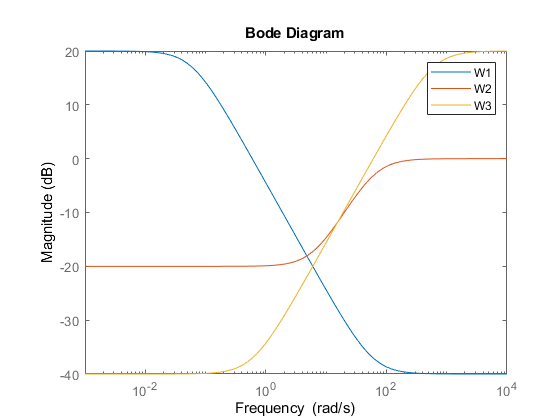


W1 = makeweight(db2mag(20),[6 db2mag(-20)],db2mag(-40)); %filtro pasa bajos
W2 = makeweight(db2mag(-20),[8 0.16],db2mag(0)); %random
W3 = makeweight(db2mag(-40),[6 db2mag(-20)],db2mag(20)); %filtro pasa altos

bodemag(W1,W2,W3)
legend

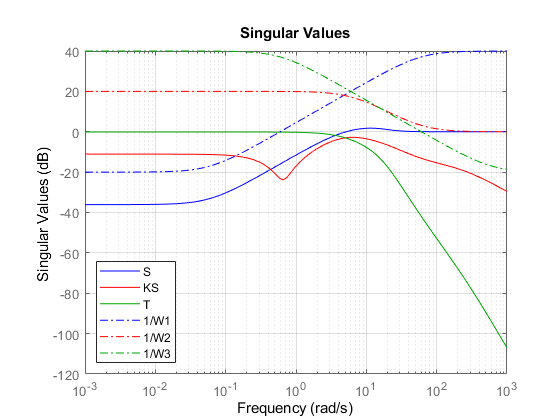


[K_Long,CL,gamma] = mixsyn(G,W1,W2,W3);
doc mixsyn
S = feedback(1,G*K_Long);
KS = K_Long*S;
T = 1-S;
sigma(S,'b',KS,'r',T,'g',1/W1,'b-.',ss(1/W2),'r-.',1/W3,'g-.',{1e-3,1e3})
legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')
grid

W1

[K_Long,CL,gamma]=mixsyn(G,W1,[],[]);
OL=series(K_Long,G);
GCL1=feedback(OL,1);
figure
step(GCL1)
hold on

W2

[K_Long,CL,gamma]=mixsyn(G,[],W2,[]);
OL=series(K_Long,G);
GCL2=feedback(OL,1);

step(GCL2)

W3

[K_Long,CL,gamma]=mixsyn(G,[],[],W3);
OL=series(K_Long,G);
GCL3=feedback(OL,1);
step(GCL3)



ALL W

[K_Long,CL,gamma]=mixsyn(G,W1,W2,W3);
OL=series(K_Long,G);
GCL=feedback(OL,1);
step(GCL)


Ajustes

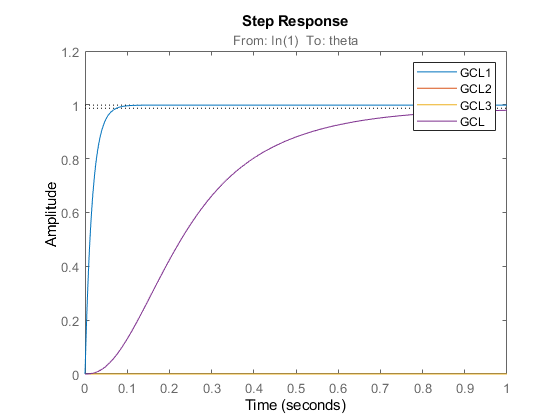

axis([0 1 0 1.2])
hold off
legend

K_Long

K =
 
  A = 
               x1          x2
   x1     -0.0597   2.982e-14
   x2      -270.6      -183.4
   x3   1.774e-16   1.122e-16
   x4      -15.83       -7.03
   x5       91.68       40.72
   x6        4534        2014
   x7   5.589e-16   3.535e-16
   x8   1.783e-15   1.128e-15
   x9   6.128e-14   3.876e-14
 
               x3          x4
   x1  -8.976e-17  -4.089e-17
   x2     -0.9476       0.249
   x3        -603  -1.538e-19
   x4    -0.05545     -0.5815
   x5      0.3211     -0.8298
   x6       15.88       -3.13
   x7  -1.064e-18  -4.846e-19
   x8  -3.394e-18    -0.05377
   x9  -1.166e-16       135.8
 
               x5          x6
   x1   2.177e-16   -4.33e-16
   x2       -1.29       2.547
   x3   8.187e-19  -1.629e-18
   x4      0.7256      -0.722
   x5      -7.144       14.85
   x6        14.2      -58.54
   x7    2.58e-18           1
   x8      0.9986  -1.637e-17
   x9       7.315  -5.627e-16
 
               x7          x8
   x1  -1.286e-14  -1.124e-20
   x2       73.93   7